# Plotting I - Follow Along Live Script 

By Samuel Bechara

## Forward

Although it is ok to use this a reference, you should not copy and paste from this document. In fact you shouldn't even copy and paste from the code that *you* have worked on. It is valuable to type the commands in yourself, every time. You are learning a new language, and just like foriegn languages, the best way to do it is to immerse yourself in it. The best way to immerse yourself is to force yourself to type the commands, everytime. There is something about banging out the commands on a keyboard that helps you wean off of using references.

**TLDR; DO NOT COPY AND PASTE WHEN WORKING ON HW OR OTHER ASSIGNMENTS**

## Using the plot() command

You can use the following links to access the economic data that I am going to be using in class. We are going to skip this step to save some time in class, but you can download it and play around with it if you need some extra practice plotting (or you are just interested!)

- [https://fred.stlouisfed.org/series/DCOILWTICO/downloaddata](https://fred.stlouisfed.org/series/DCOILWTICO/downloaddata)

- [https://fred.stlouisfed.org/series/GASREGCOVW/downloaddata](https://fred.stlouisfed.org/series/GASREGCOVW/downloaddata)

- [https://fred.stlouisfed.org/series/DPROPANEMBTX/downloaddata](https://fred.stlouisfed.org/series/DPROPANEMBTX/downloaddata)

clear
clc
close all

Lets go ahead and clear stuff up and load the variables.

load('hist_energy_prices.mat')

You should notice that three variables were loaded into your workspace. All variables correspond to weekly values and include values for all dates between 1992-07-09 and 2016-09-19. 

The variables (and units) are:

- `gas_price` ($/gallon)

- `oil_price` ($/barrel)

- `propane_price `($/gallon)

Now we need to define a time array to plot against. Since all of the variables are the same size, we only need *one* time array.

t = 1:length(gas_price)

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Alright, lets plot!

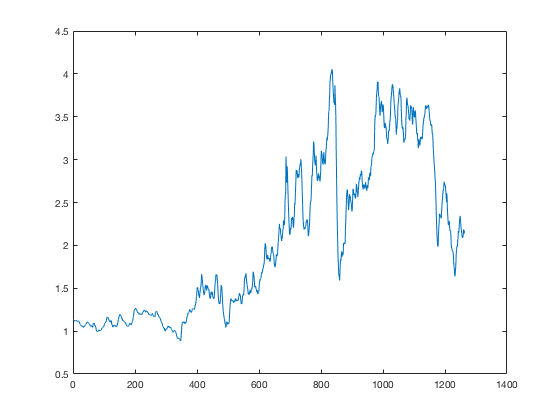

plot(t,gas_price)

## Making graphs look good

Well we have a plot but it doesn't really tell us anything. Let's add text and labels to make it look better.

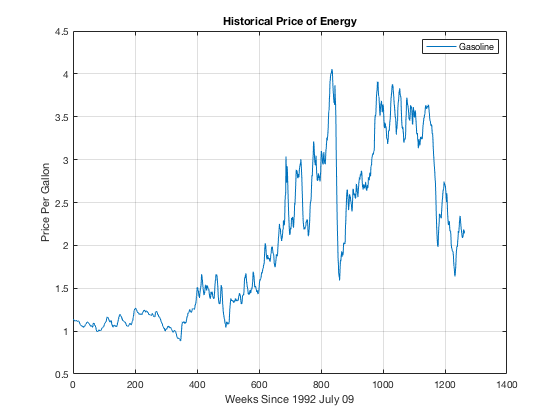

title('Historical Price of Energy')
xlabel('Weeks Since 1992 July 09')
ylabel('Price Per Gallon')
legend('Gasoline')
grid

Much better! Note that all of the commands used above besides `grid`, take a string as an argument.

## Making it your own

First, lets tell MATLAB to open up a new figure. If we do not do this and we issue another plot command, MATLAB will overwrite the current figure. Then lets plot gas_price again but this time lets make it look different.

figure;
plot(t,gas_price,'gd') %gd is green diamond.g-- would be green dashed line
x_name = 'Weeks since 1992 July 09'

x_name = 'Weeks since 1992 July 09'

y_name = 'Price Per Gallon'

y_name = 'Price Per Gallon'

energy_title = 'Historical Prices of Energy'

energy_title = 'Historical Prices of Energy'

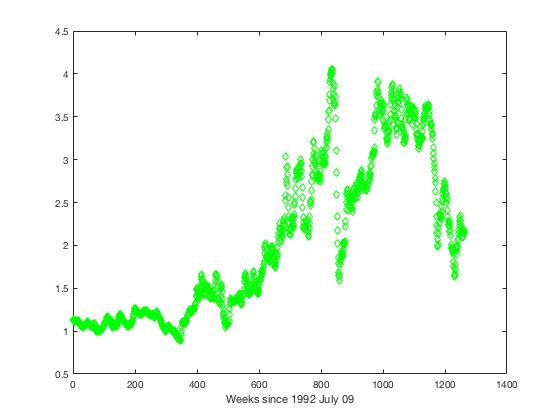


xlabel(x_name)

## Plotting on the same figure (method 1)

Lets open up a new figure, but this time plot two quantities on the same graph

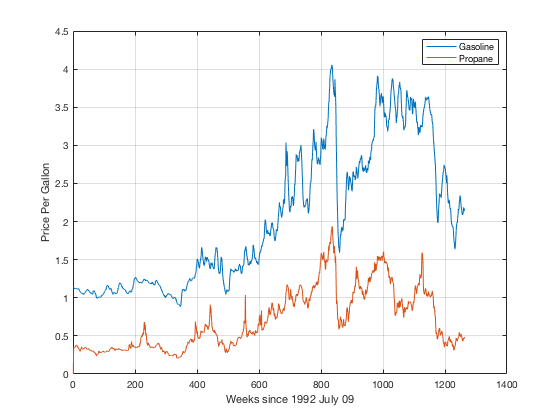

figure;
plot(t,gas_price,t,propane_price)
legend('Gasoline','Propane')
xlabel(x_name)
ylabel(y_name)
grid

## Plotting on the same figure (method 2)

As promised, there are two ways to plot two figures on the same graph. Let's explore the second way to do this. 

But first lets manipulate the data. From our chart above it is obvious that a gallon of gasoline has ALWAYS been more expensive than a gallon of propane. It might be easier to tell how the prices have changed over time if we shift the propane price up to the gas price. We will no longer be able to tell the absoulte cost, but we will be able to see how market forces change the price of both products.

Then we will plot. Lets change the colors and leave the grid off so we can distinguish it easily from the plot above.

figure;
propane_normal = (((propane_price-min(propane_price))/max(propane_price))-min(propane_price)))
hold on;
plot(t,prop)
hold off;

This is interesting, it appears that market forces impacted the price of propane and gasoline fairly linearlly until sometime after 1000 weeks after the data started. It is hard to tell from the graph where the maximum difference was. Good thing we have MATLAB to help us figure it out! Let's add it as a point on the graph.

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

## Lets look at a specific range of years

For example (and for no particular reason) lets look at what happend between July 2007 and July 2009. Remember, we know when the data started (July 1992), and we know how many weeks are in the year.

So the steps are to plot the oil vs time, do some math, then adjust our plot accordingly.

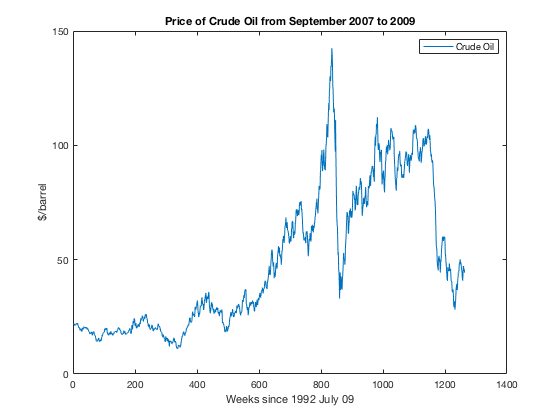

figure;
plot(t,oil_price);
xlabel(x_name);
ylabel('$/barrel');
legend('Crude Oil');
title('Price of Crude Oil from September 2007 to 2009');


% Define the year for our range and some constants


% do some math
yr_difference=yr_plot_start-yr_data_start;

Undefined function or variable 'yr_plot_start'.

yr_range=yr_plot_end-yr_plot_start;
week_start=yr_difference*weeks_per_year;
week_end=week_start+yr_range*weeks_per_year;

% MATLAB is really good at coming up with nice axis so lets use it
% notice that expressions can separate plotting functions and still work!


For good exam practice, see if you can figure out what the minimum and maximum price per barrel was in between those dates, plot them as points on this graph, and figure out what the date was where the minimum and maximum price occured.